We choose a function over the interval $[0,1]$. 

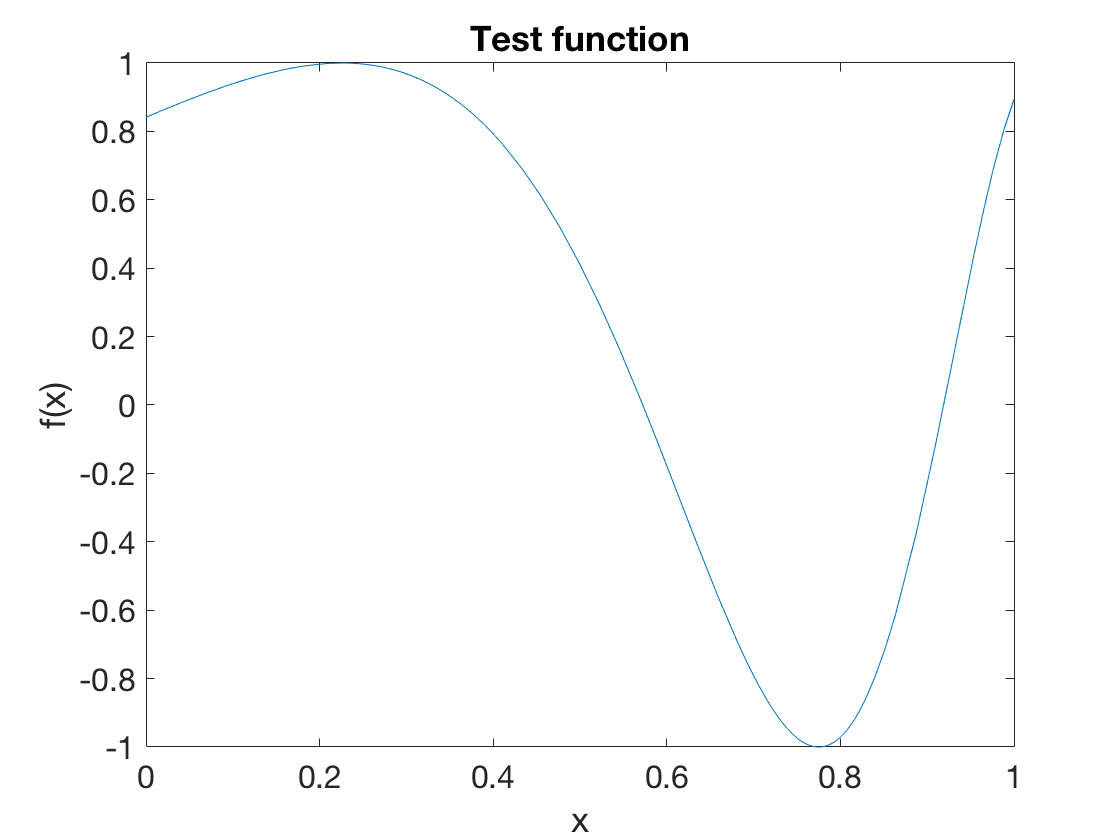

f = @(x) sin(exp(2*x));
fplot(f,[0 1])
xlabel('x'), ylabel('f(x)') % ignore this line
title('Test function')    % ignore this line

We interpolate it at equally spaced nodes for increasing values of $n$. We will sample the interpolant at a large number of points in order to estimate the interpolation error. 

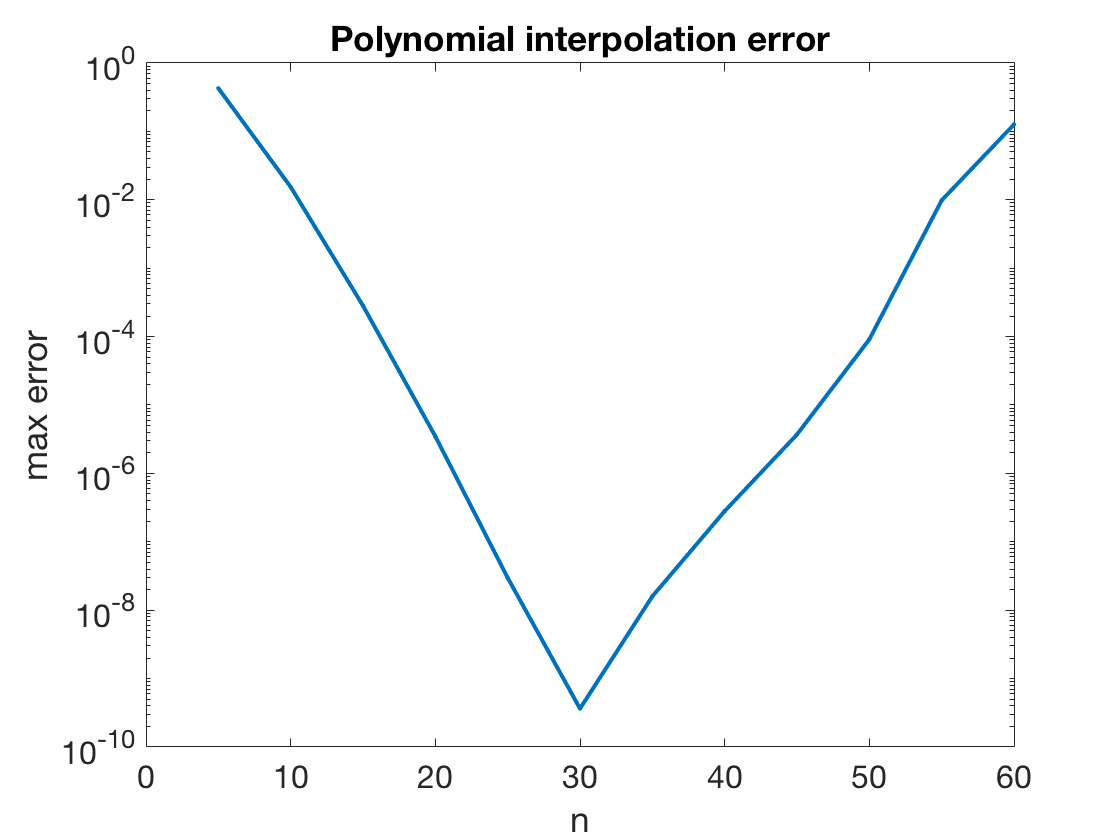

n = (5:5:60)';   err = 0*n;
x = linspace(0,1,1001)';         % for measuring error
for k = 1:length(n) 
  t = linspace(0,1,n(k)+1)';     % equally spaced nodes
  y = f(t);                      % interpolation data
  p = polyinterp(t,y);
  err(k) = norm( f(x)-p(x), inf );
end
semilogy(n,err,'.-')
xlabel('n'), ylabel('max error')   % ignore this line
title('Polynomial interpolation error')   % ignore this line

Initially the error decreases exponentially, i.e. as $O(K^{-n})$ for some $K>1$. However, around $n=30$ the error starts to *grow* exponentially. 